# **Assignment-1**

# Submitted by:- Priyanshu Rawat

# Question-2

#### Case-1) When dx=2 & velocity distribution=6

clc;
clear;
v_grid=linspace(0,5,6); 
dx=2; % Position increament 0.2
X=[0:dx:10];
Ns=numel(X)-1; % Number of stages
Nv=numel(v_grid); % Number of velocity distributions 
amin=-2; % Acceleration (accel) lower bound
amax=2; % Acceleration (accel) upper bound
count=1;
cost = zeros(Nv,Ns); % Initialized cost matrix with zeroes

for i=Ns:-1:1
    for j=1:Nv;
        for k=1:Nv;
            dt(j,k)=2*dx/(v_grid(j)+v_grid(k));
            a(j,k)=(v_grid(j)^2-v_grid(k)^2)/(2*dx);
            if a(j,k) < amin || a(j,k) > amax
                dt(j,k) = inf; 
            end
        end
    end
    if i==Ns && count==1 % for last stage taking only the '0' velocity in consideration
        cost(:,i) = flip(dt(1,:));
        accel(:,i) = flip(a(1,:));
        count = 0;
    end  
    % for other stages except last stage 
    if i~=Ns
        prev_cost = flip(transpose(cost(:,i+1))); % taking stage cost into a column vector
        [least_costs,indices] = min(dt + meshgrid(prev_cost,prev_cost),[],2); % indices -> stores column indices of least cost for every node in a stage 
        cost(:,i) = flip(least_costs);
        % indices -> stores column indices of least cost for every node in a stage 
        l=1;
        while l<(Nv+1)
            accel((Nv+1)-l,i) = a(indices(l,1),l); % filling the value of acceleration starting from second last column and last row
            l = l+1;
        end
    end
end

%% Printing the 'cost' and 'acceleration' matrix for 
% disp('Cost and Acceleration matrix :-')
cost;
accel;

%%%% Forward pass to find values of cost, acceleration and velocity profile 

% Starting from rest (velocity = 0)
velocity_profile(1)=0;
accel_profile(1) = accel(end,1);
cost_profile(1) = cost(end,1);

% Finding nodes based on the difference of velocity at every stage from the Velocity grid 
veldiff = 0;
for i = 2:Ns
    velocity_profile(i) = real(sqrt(velocity_profile(i-1)^2 + 2*accel_profile(i-1)*dx));
    for s = 1:Nv
        veldiff(s) =  velocity_profile(i)-v_grid(s);
    end
% Saving index of node with least positive velocity difference 
    [minDiff, indexOfMin] = min(abs(veldiff));
    velocity_profile(i) = v_grid(indexOfMin);
    accel_profile(i) = accel(indexOfMin,i-1);
    cost_profile(i) = cost(indexOfMin,i-1);
end

% Final stage of rest (cost, velocity and acceleration at last stage should be zero)
velocity_profile(Ns+1)=0;
cost_profile(Ns+1) = 0;
accel_profile(Ns+1) = 0

accel_profile =     1.0000    1.7500    1.2500    2.0000    1.0000         0


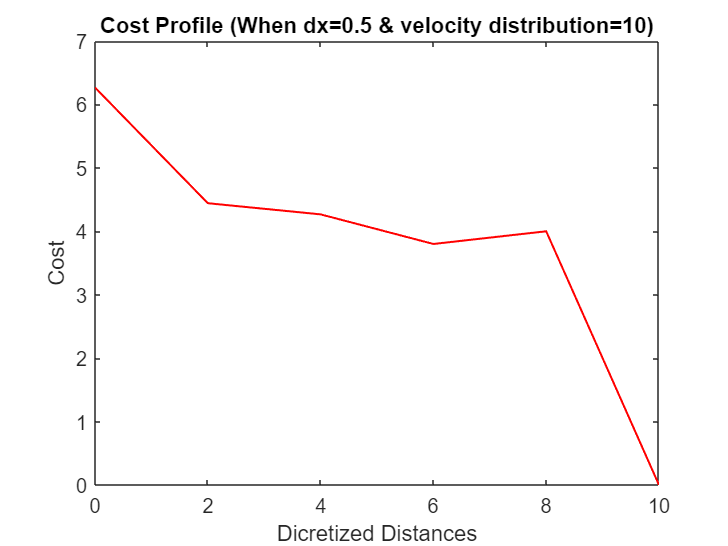


%% Cost profile plot
figure
plot(X, cost_profile, LineWidth=1, Color="r")
title("Cost Profile (When dx=0.5 & velocity distribution=10)")
xlabel("Dicretized Distances")
ylabel("Cost")

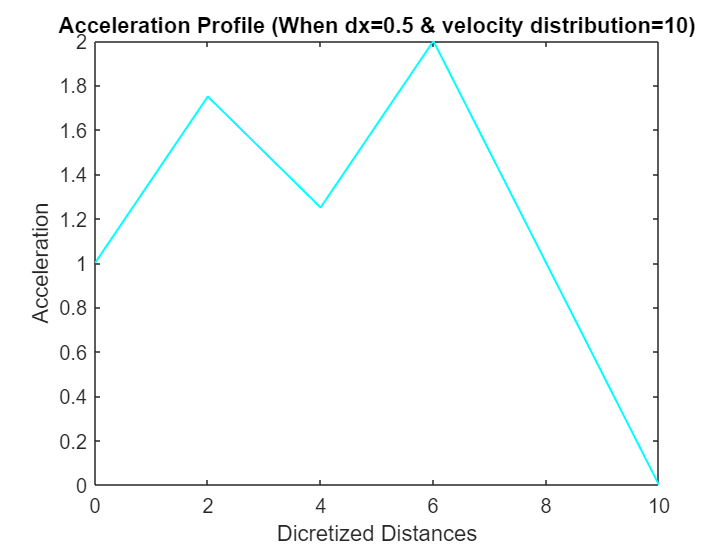


%% Acceleration profile plot
figure
plot(X, accel_profile, LineWidth=1, Color="c")
title("Acceleration Profile (When dx=0.5 & velocity distribution=10)")
xlabel("Dicretized Distances")
ylabel("Acceleration")

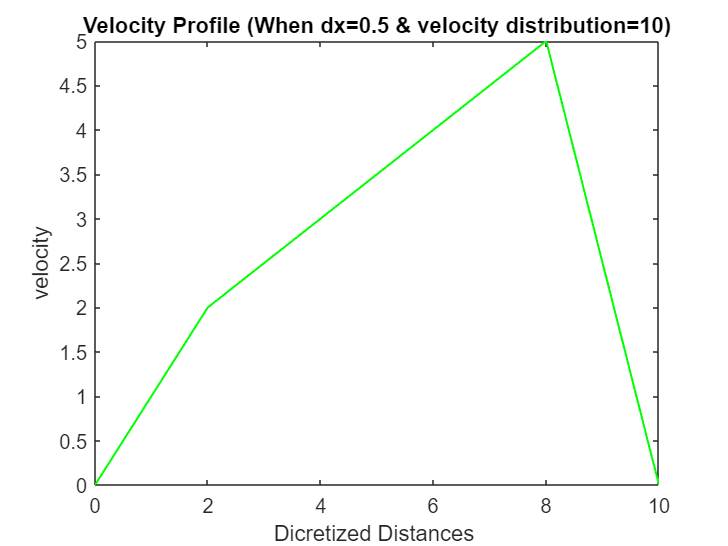


%% Velocity profile plot
figure
plot(X, velocity_profile, LineWidth=1, Color="g")
title("Velocity Profile (When dx=0.5 & velocity distribution=10)")
xlabel("Dicretized Distances ")
ylabel("velocity")

#### Case-2) When dx=0.1 and velocity distribution = 50

clc;
clear;
v_grid=linspace(0,5,50);
dx = 0.1; % Position increament
X = [0:dx:10];
Ns=numel(X)-1; % Number of stages
Nv=numel(v_grid); % Number of velocity distributions 
amin=-3; % Acceleration (accel) lower bound
amax=3; % Acceleration (accel) upper bound
count=1;
cost = zeros(Nv,Ns); % Initialized cost matrix with zeroes

for i=Ns:-1:1
    for j=1:Nv;
        for k=1:Nv;
            dt(j,k)=2*dx/(v_grid(j)+v_grid(k));
            a(j,k)=(v_grid(j)^2-v_grid(k)^2)/(2*dx);
            if a(j,k) < amin || a(j,k) > amax
                dt(j,k) = inf; 
            end
        end
    end
    if i==Ns && count==1 % for last stage taking only the '0' velocity in consideration
        cost(:,i) = flip(dt(1,:));
        accel(:,i) = flip(a(1,:));
        count = 0;
    end  
    % for other stages except last stage
    if i~=Ns
        prev_cost = flip(transpose(cost(:,i+1))); % taking stage cost into a column vector
        [least_costs,indices] = min(dt + meshgrid(prev_cost,prev_cost),[],2); % indices -> stores column indices of least cost for every node in a stage 
        cost(:,i) = flip(least_costs);
        % indices -> stores column indices of least cost for every node in a stage 
        l=1;
        while l<(Nv+1)
            accel((Nv+1)-l,i) = a(indices(l,1),l); % filling the value of acceleration starting from second last column and last row
            l = l+1;
        end
    end
end

%% Printing the 'cost' and 'acceleration' matrix for 
% disp('Cost and Acceleration matrix :-')
cost;
accel;

%%%% Forward pass to find values of cost, acceleration and velocity profile
% Cost
[M,I] = min(cost(:,2:Ns),[],1, "linear"); % Taking the least cost and its index
disp('Cost profile :-')

Cost profile :-


cost_profile = [cost(Nv,1) M 0]

cost_profile =     4.6417    3.9767    3.9429    3.9091    3.8754    3.8416    3.8078    3.7740    3.7402    3.7064    3.6726    3.6388    3.6050    3.5712    3.5374    3.5036    3.4698    3.4360    3.4022    3.3685    3.3347    3.3009    3.2671    3.2333    3.1995    3.1657    3.1319    3.0981    3.0643    3.0305    2.9967    2.9629    2.9291    2.8954    2.8616    2.8278    2.7940    2.7602    2.7264    2.6926    2.6588    2.6250    2.5912    2.5574    2.5236    2.4898    2.4560    2.4222    2.3885    2.3547



% Acceleration
disp('Acceleration profile :-')

Acceleration profile :-


accel_profile = [accel(Nv,1) accel(I+Nv)  0] % Taking the acceleration values corresponding to the least cost in every stage (except first and last)  

accel_profile =     2.5510         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0



% Velocity
velocity_profile(1) = 0;
for m = 2:Ns
    velocity_profile(m) = real(sqrt(velocity_profile(m-1)^2 + 2*accel_profile(m-1)*dx));
end
velocity_profile(Ns+1) = 0;
disp('Velocity profile :-')

Velocity profile :-


velocity_profile

velocity_profile =          0    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143    0.7143


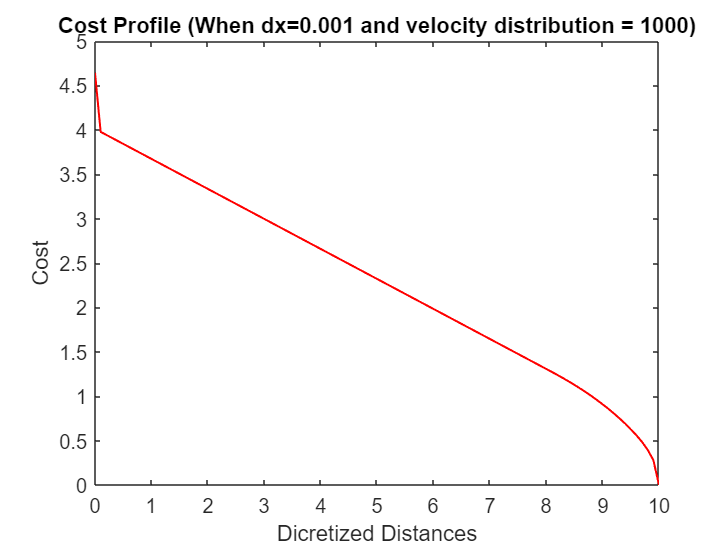


%% Cost profile plot
figure
plot(X, cost_profile, LineWidth=1, Color="r")
title("Cost Profile (When dx=0.001 and velocity distribution = 1000)")
xlabel("Dicretized Distances")
ylabel("Cost")
xticks(0:Ns);

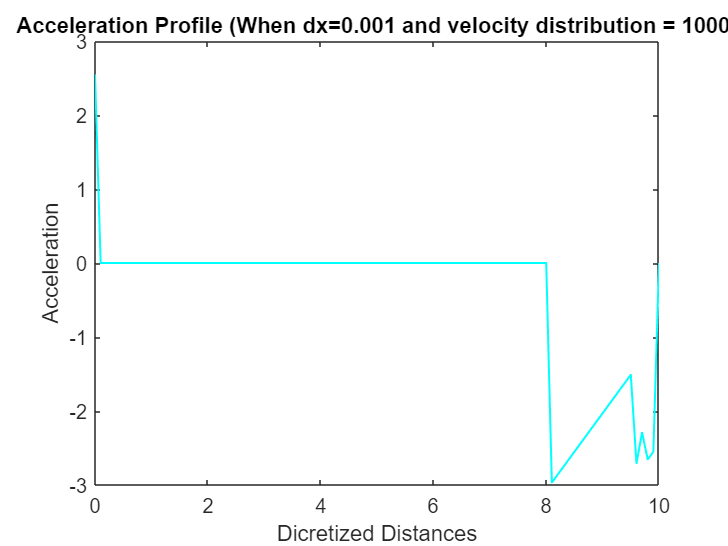


%% Acceleration profile plot
figure
plot(X, accel_profile, LineWidth=1, Color="c")
title("Acceleration Profile (When dx=0.001 and velocity distribution = 1000)")
xlabel("Dicretized Distances")
ylabel("Acceleration")

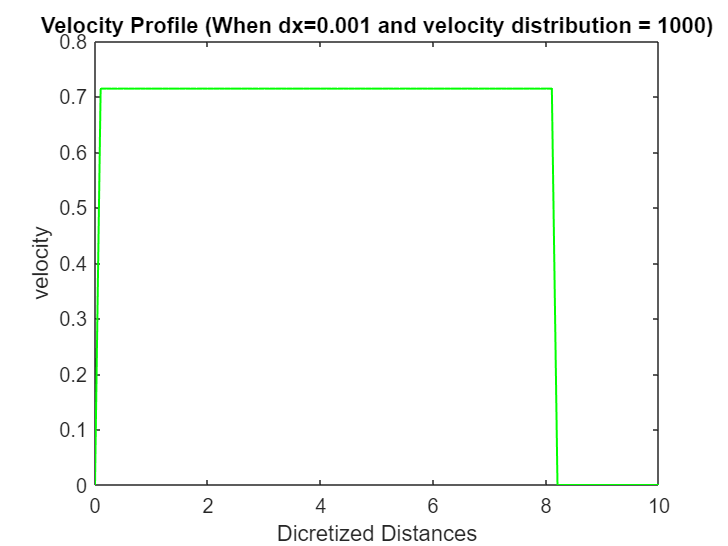


%% Velocity profile plot
figure
plot(X, velocity_profile, LineWidth=1, Color="g")
title("Velocity Profile (When dx=0.001 and velocity distribution = 1000)")
xlabel("Dicretized Distances")
ylabel("velocity")

#### Case-3) When dx=0.01 and velocity distribution = 50

clc;
clear;
v_grid=linspace(0,5,50);
dx = 0.01; % Position increament
X = [0:dx:10];
Ns=numel(X)-1; % Number of stages
Nv=numel(v_grid); % Number of velocity distributions 
amin=-3; % Acceleration (accel) lower bound
amax=3; % Acceleration (accel) upper bound
count=1;
cost = zeros(Nv,Ns); % Initialized cost matrix with zeroes

for i=Ns:-1:1
    for j=1:Nv;
        for k=1:Nv;
            dt(j,k)=2*dx/(v_grid(j)+v_grid(k));
            a(j,k)=(v_grid(j)^2-v_grid(k)^2)/(2*dx);
            if a(j,k) < amin || a(j,k) > amax
                dt(j,k) = inf; 
            end
        end
    end
    if i==Ns && count==1 % for last stage taking only the '0' velocity in consideration
        cost(:,i) = flip(dt(1,:));
        accel(:,i) = flip(a(1,:));
        count = 0;
    end  
    % for other stages except last stage
    if i~=Ns
        prev_cost = flip(transpose(cost(:,i+1))); % taking stage cost into a column vector
        [least_costs,indices] = min(dt + meshgrid(prev_cost,prev_cost),[],2); % indices -> stores column indices of least cost for every node in a stage 
        cost(:,i) = flip(least_costs);
        % indices -> stores column indices of least cost for every node in a stage 
        l=1;
        while l<(Nv+1)
            accel((Nv+1)-l,i) = a(indices(l,1),l); % filling the value of acceleration starting from second last column and last row
            l = l+1;
        end
    end
end

%% Printing the 'cost' and 'acceleration' matrix for 
% disp('Cost and Acceleration matrix :-')
cost;
accel;

%% Forward pass to find values of cost, acceleration and velocity profile
% Cost
[M,I] = min(cost(:,2:Ns),[],1, "linear"); % Taking the least cost and its index
disp('Cost profile :-')

Cost profile :-


cost_profile = [cost(Nv,1) M 0]

cost_profile =    32.8104   32.7059   32.6732   32.6405   32.6079   32.5752   32.5425   32.5099   32.4772   32.4445   32.4119   32.3792   32.3465   32.3139   32.2812   32.2485   32.2159   32.1832   32.1505   32.1179   32.0852   32.0525   32.0199   31.9872   31.9545   31.9219   31.8892   31.8565   31.8239   31.7912   31.7585   31.7259   31.6932   31.6605   31.6279   31.5952   31.5625   31.5299   31.4972   31.4645   31.4319   31.3992   31.3665   31.3339   31.3012   31.2685   31.2359   31.2032   31.1705   31.1379



% Acceleration
disp('Acceleration profile :-')

Acceleration profile :-


accel_profile = [accel(Nv,1) accel(I+Nv)  0] % Taking the acceleration values corresponding to the least cost in every stage (except first and last)  

accel_profile =     2.0825         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0



% Velocity
velocity_profile(1) = 0;
for m = 2:Ns+1
    velocity_profile(m) = real(sqrt(velocity_profile(m-1)^2 + 2*accel_profile(m-1)*dx));
end
velocity_profile(Ns+1) = 0;
disp('Velocity profile :-')

Velocity profile :-


velocity_profile

velocity_profile =          0    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041    0.2041


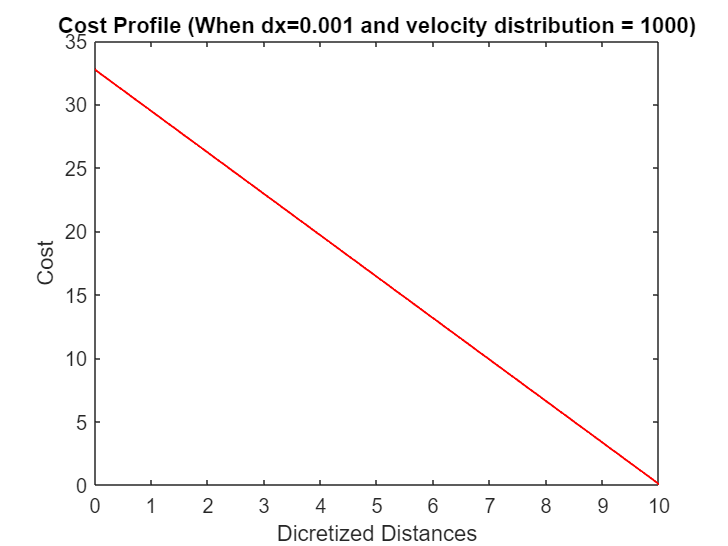


%% Cost profile plot
figure
plot(X, cost_profile, LineWidth=1, Color="r")
title("Cost Profile (When dx=0.001 and velocity distribution = 1000)")
xlabel("Dicretized Distances")
ylabel("Cost")
xticks(0:Ns);

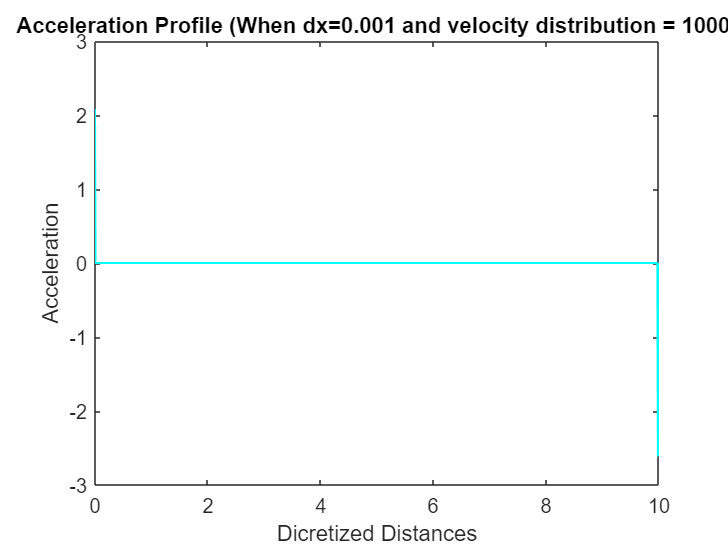


%% Acceleration profile plot
figure
plot(X, accel_profile, LineWidth=1, Color="c")
title("Acceleration Profile (When dx=0.001 and velocity distribution = 1000)")
xlabel("Dicretized Distances")
ylabel("Acceleration")

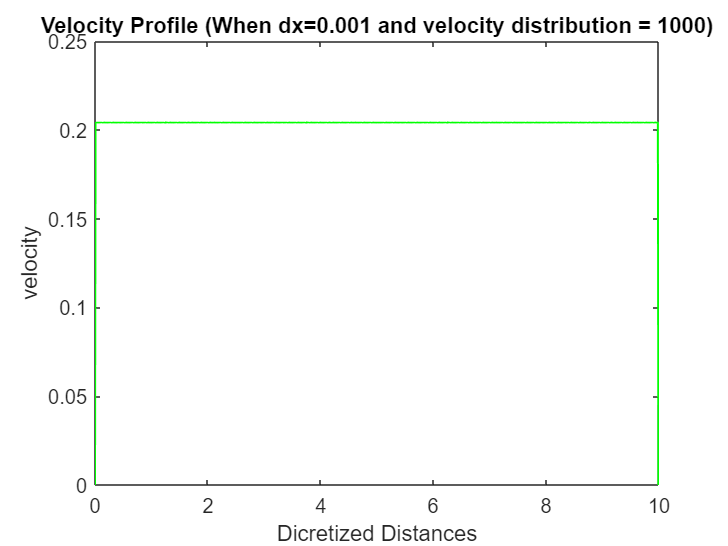


%% Velocity profile plot
figure
plot(X, velocity_profile, LineWidth=1, Color="g")
title("Velocity Profile (When dx=0.001 and velocity distribution = 1000)")
xlabel("Dicretized Distances")
ylabel("velocity")

# Question-3

#### Taking dx=2 and velocity distribution = 6 

#### *(Assuming regeneration; therefore considering the negative cost values)*

#### Case-1) When q=0; i.e., cost function does not depend on the trip time

clc;
clear;
v_grid=linspace(0,5,6);
dx=2; % position increament
X=[0:dx:10];
Ns=numel(X)-1; % number of stages
Nv=numel(v_grid); % number of velocity distributions 
amin=-3; % acceleration (accel) lower bound
amax=3; % acceleration (accel) upper bound
m=2; % mass of the cart
A=0.1; % frontal area
Cd=0.4; % drag coefficient
rho=1.204; % air density
mu=0.2; % rolling resistance coefficient
g=10; % acceleration due to gravity
cost = zeros(Nv,Ns); % Initialized cost matrix with zeroes
C1 = 1/2*Cd*rho*A;
q=0;
count=1; 

for i=Ns:-1:1
    for j=1:Nv;
        for k=1:Nv;
            a(j,k)=(v_grid(j)^2-v_grid(k)^2)/(2*dx);
            dE(j,k)= (m*a(j,k)+mu*m*g)*dx + C1*(1/2*dx)*(v_grid(j).^2+v_grid(k).^2) + q*2*dx/(v_grid(j)+v_grid(k)); % Considering regeneration
            if a(j,k) < amin || a(j,k) > amax
                dE(j,k) = inf; 
            end
        end
    end
    if i==Ns && count==1 % for last stage taking only the '0' velocity in consideration
        cost(:,i) = flip(dE(1,:));
        accel(:,i) = flip(a(1,:));
        count = 0;
    end  
    % for other stages except last stage 
    if i~=Ns
        prev_cost = flip(transpose(cost(:,i+1))); % taking stage cost into a column vector
        [least_costs,indices] = min(dE + meshgrid(prev_cost,prev_cost),[],2); % indices -> stores column indices of least cost for every node in a stage 
        cost(:,i) = flip(least_costs);
        % indices -> stores column indices of least cost for every node in a stage 
        l=1;
        while l<(Nv+1)
            accel((Nv+1)-l,i) = a(indices(l,1),l); % filling the value of acceleration starting from second last column and last row
            l = l+1;
        end
    end
end

disp('Q3) When q=0 :-')

Q3) When q=0 :-


% disp('Cost and Acceleration matrix :-')
% cost;
% accel;

%% Forward pass to find values of cost, acceleration and velocity profile
% Cost
[M,I] = min(cost(:,2:Ns),[],1, "linear"); % Taking the least cost and its index
disp('Cost profile(q=0) :-')

Cost profile(q=0) :-


cost_profile1 = [cost(Nv,1) M 0]

cost_profile1 =    22.5298   14.4816    6.4816   -1.5666   -0.7833         0



% Acceleration
disp('Acceleration profile(q=0) :-')

Acceleration profile(q=0) :-


accel_profile1 = [accel(Nv,1) accel(I+Nv)  0] % Taking the acceleration values corresponding to the least cost in every stage (except first and last)  

accel_profile1 =     0.2500    0.2500    0.2500    2.2500   -2.2500         0



% Velocity
velocity_profile1(1) = 0;
% accel_profile1 = [accel(Nv,1) v_grid(I+Nv)  0]
for m = 2:Ns+1
    velocity_profile1(m) = real(sqrt(velocity_profile1(m-1)^2 + 2*accel_profile1(m-1)*dx));
end
velocity_profile1(Ns+1) = 0;
disp('Velocity profile(q=0) :-')

Velocity profile(q=0) :-


velocity_profile1

velocity_profile1 =          0    1.0000    1.4142    1.7321    3.4641         0


#### Case-2) When q=2; i.e., cost function does not depend on the trip time

v_grid=linspace(0,5,6);
dx=2; % position increament
X=[0:dx:10];
Ns=numel(X)-1; % number of stages
Nv=numel(v_grid); % number of velocity distributions 
amin=-3; % acceleration (accel) lower bound
amax=3; % acceleration (accel) upper bound
m=2; % mass of the cart
A=0.1; % frontal area
Cd=0.4; % drag coefficient
rho=1.204; % air density
mu=0.2; % rolling resistance coefficient
g=10; % acceleration due to gravity
cost = zeros(Nv,Ns); % Initialized cost matrix with zeroes
C1 = 1/2*Cd*rho*A;
q=2;
count=1; 

for i=Ns:-1:1
    for j=1:Nv;
        for k=1:Nv;
            a(j,k)=(v_grid(j)^2-v_grid(k)^2)/(2*dx);
            dE(j,k)= (m*a(j,k)+mu*m*g)*dx + C1*(1/2*dx)*(v_grid(j).^2+v_grid(k).^2) + q*2*dx/(v_grid(j)+v_grid(k)); % Considering regeneration
            if a(j,k) < amin || a(j,k) > amax
                dE(j,k) = inf; 
            end
        end
    end
    if i==Ns && count==1 % for last stage taking only the '0' velocity in consideration
        cost(:,i) = flip(dE(1,:));
        accel(:,i) = flip(a(1,:));
        count = 0;
    end  
    % for other stages except last stage 
    if i~=Ns
        prev_cost = flip(transpose(cost(:,i+1))); % taking stage cost into a column vector
        [least_costs,indices] = min(dE + meshgrid(prev_cost,prev_cost),[],2); % indices -> stores column indices of least cost for every node in a stage 
        cost(:,i) = flip(least_costs);
        % indices -> stores column indices of least cost for every node in a stage 
        l=1;
        while l<(Nv+1)
            accel((Nv+1)-l,i) = a(indices(l,1),l); % filling the value of acceleration starting from second last column and last row
            l = l+1;
        end
    end
end

disp('Q3) When q=2 :-')

Q3) When q=2 :-


% disp('Cost and Acceleration matrix :-')
% cost;
% accel;

%% Forward pass to find values of cost, acceleration and velocity profile
% Cost
[M,I] = min(cost(:,2:Ns),[],1, "linear"); % Taking the least cost and its index during forward propogation
disp('Cost profile(q=2) :-')

Cost profile(q=2) :-


cost_profile2 = [cost(Nv,1) M 0]

cost_profile2 =    33.0233   23.2565   13.5335    3.7668    1.8834         0



% Acceleration
disp('Acceleration profile(q=2) :-')

Acceleration profile(q=2) :-


accel_profile2 = [accel(Nv,1) accel(I+Nv)  0] % Taking the acceleration values corresponding to the least cost in every stage (except first and last)  

accel_profile2 =     2.2500    2.2500    2.2500    2.2500   -2.2500         0



% Velocity
velocity_profile2(1) = 0;
for m = 2:Ns+1
    velocity_profile2(m) = real(sqrt(velocity_profile2(m-1)^2 + 2*accel_profile2(m-1)*dx));
end
velocity_profile2(Ns+1) = 0;
disp('Velocity profile(q=2) :-')

Velocity profile(q=2) :-


velocity_profile2

velocity_profile2 =          0    3.0000    4.2426    5.1962    6.0000         0


#### Case-4) When q=4; i.e., cost function does not depend on the trip time

v_grid=linspace(0,5,6);
dx=2; % position increament
X=[0:dx:10];
Ns=numel(X)-1; % number of stages
Nv=numel(v_grid); % number of velocity distributions 
amin=-3; % acceleration (accel) lower bound
amax=3; % acceleration (accel) upper bound
m=2; % mass of the cart
A=0.1; % frontal area
Cd=0.4; % drag coefficient
rho=1.204; % air density
mu=0.2; % rolling resistance coefficient
g=10; % acceleration due to gravity
cost = zeros(Nv,Ns); % Initialized cost matrix with zeroes
C1 = 1/2*Cd*rho*A;
q=4;
count=1; 

for i=Ns:-1:1
    for j=1:Nv;
        for k=1:Nv;
            a(j,k)=(v_grid(j)^2-v_grid(k)^2)/(2*dx);
            dE(j,k)= (m*a(j,k)+mu*m*g)*dx + C1*(1/2*dx)*(v_grid(j).^2+v_grid(k).^2) + q*2*dx/(v_grid(j)+v_grid(k)); % Considering regeneration
            if a(j,k) < amin || a(j,k) > amax
                dE(j,k) = inf; 
            end
        end
    end
    if i==Ns && count==1 % for last stage taking only the '0' velocity in consideration
        cost(:,i) = flip(dE(1,:));
        accel(:,i) = flip(a(1,:));
        count = 0;
    end  
    % for other stages except last stage 
    if i~=Ns
        prev_cost = flip(transpose(cost(:,i+1))); % taking stage cost into a column vector
        [least_costs,indices] = min(dE + meshgrid(prev_cost,prev_cost),[],2); % indices -> stores column indices of least cost for every node in a stage 
        cost(:,i) = flip(least_costs);
        % indices -> stores column indices of least cost for every node in a stage 
        l=1;
        while l<(Nv+1)
            accel((Nv+1)-l,i) = a(indices(l,1),l); % filling the value of acceleration starting from second last column and last row
            l = l+1;
        end
    end
end

disp('Q3) When q=4 :-')

Q3) When q=4 :-


% disp('Cost and Acceleration matrix :-')
% cost; 
% accel;

%% Forward pass to find values of cost, acceleration and velocity profile
% Cost
[M,I] = min(cost(:,2:Ns),[],1, "linear"); % Taking the least cost and its index
disp('Cost profile(q=4) :-')

Cost profile(q=4) :-


cost_profile3 = [cost(Nv,1) M 0]

cost_profile3 =    41.6461   30.5663   19.8910    8.7909    4.5501         0



% Acceleration
disp('Acceleration profile(q=4) :-')

Acceleration profile(q=4) :-


accel_profile3 = [accel(Nv,1) accel(I+Nv)  0] % Taking the acceleration values corresponding to the least cost in every stage (except first and last)  

accel_profile3 =     2.2500    2.0000    2.0000    2.0000   -2.2500         0



% Velocity
velocity_profile3(1) = 0;
for m = 2:Ns+1
    velocity_profile3(m) = real(sqrt(velocity_profile3(m-1)^2 + 2*accel_profile3(m-1)*dx));
end
velocity_profile3(Ns+1) = 0;
disp('Velocity profile(q=4) :-')

Velocity profile(q=4) :-


velocity_profile3

velocity_profile3 =          0    3.0000    4.1231    5.0000    5.7446         0


#### Comparing cost, acceleration and velocity profiles (when q=1,2,4)

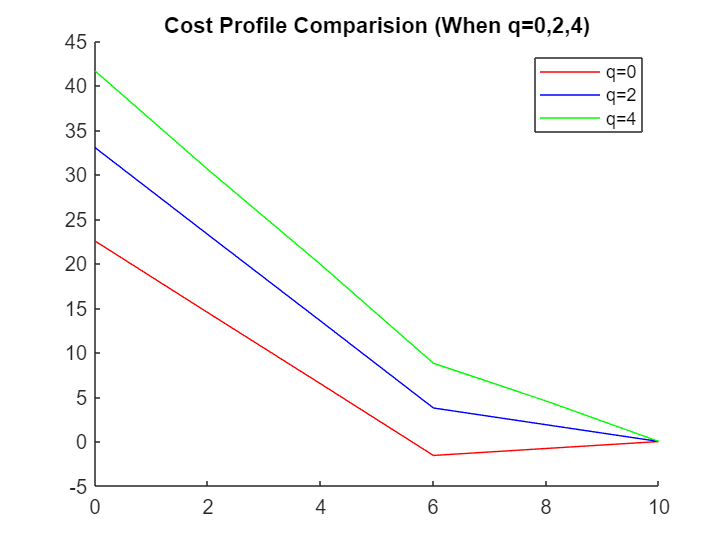

%% Cost profile plot comparision
figure
hold on
plot(X,cost_profile1, 'r')
title('Cost Profile Comparision (When q=0,2,4)')
plot(X,cost_profile2, 'b')
plot(X,cost_profile3, 'g')
legend("q=0","q=2","q=4")
hold off

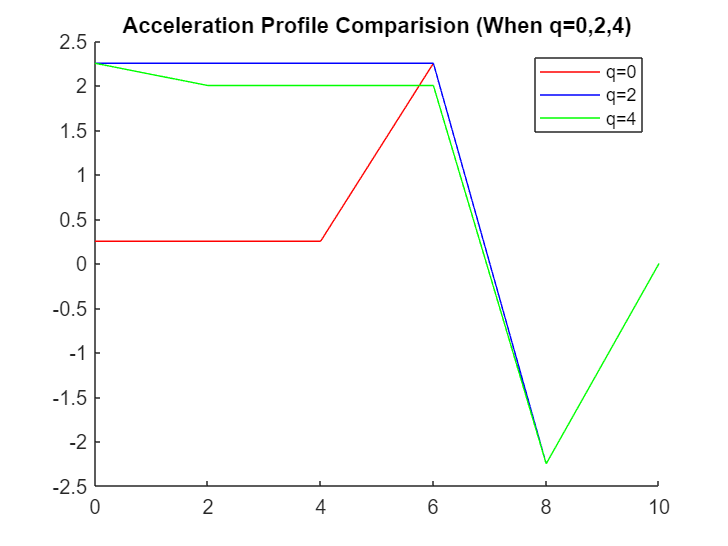


%% Cost acceleration plot comparision
figure
hold on
plot(X,accel_profile1, 'r')
title('Acceleration Profile Comparision (When q=0,2,4)')
plot(X,accel_profile2, 'b')
plot(X,accel_profile3, 'g')
legend("q=0","q=2","q=4")
hold off

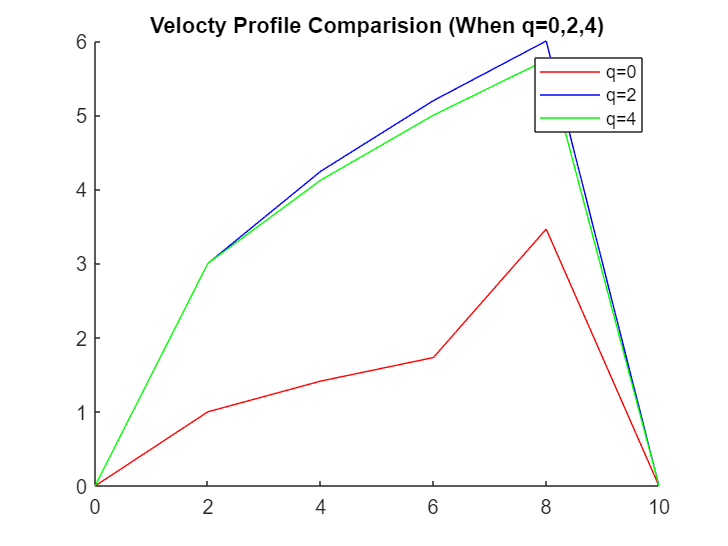


%% Cost velocity plot comparision
figure
hold on
plot(X,velocity_profile1, 'r')
title('Velocty Profile Comparision (When q=0,2,4)')
plot(X,velocity_profile2, 'b')
plot(X,velocity_profile3, 'g')
legend("q=0","q=2","q=4")
hold off

As seen in the graphs above;

- There was a increase in cost with the increase in the value of `q`, which is reasonable since including the 'total trip time' into the cost function should increase the value of the cost function, as correspondigly velocity and acceleration is also increased. 

- In the velocity graph, it can be seen that velocities in the cases where `q` is non-zero are higher compared to when the value of `q` is equal to `0` and 'total trip time' was ignored.

- Similarly, from the acceleration graph , it can be seen that including the 'total trip time' in the cost function resulted in a higher value of acceleration.

- Lastly, when `q` was equal to `0`, as accelration went down the value of cost function went below `0` impying the regeneration capability.  

# Question-4

clc;
clear;
v_grid=linspace(0,5,10); % Velocity distribution of 10
dx=0.1; % Position increament 2
X=[0:dx:10];
Ns=numel(X)+1; % Number of discretized distance
Nv=numel(v_grid); % Number of velocity distributions 

%% Taking v^2 as the variable to optimze\

x = zeros(1,Ns)';

% Initial point
x0 = zeros(Ns,1);

% Equality constraints
Aeq = zeros(2,Ns);
Aeq(1,1)=1;
Aeq(2,Ns)=1;
Beq = [0; 0];

% Linear inequality constraints
A = zeros(2*length(x)-2,length(x));
b = ones(length(A),1);
b = b.*(3*2*dx);

% Lower and upper bound limits for v^2 (i.e., 0 and 25)
lb = zeros(1,Ns);
ub = (ones(1,Ns)).*25;

j = 1;
for i=2:1:length(A)/2+1
    A(j,i-1) = 1;
    A(j,i) = -1;
    j =j+1;
end
for k=2:1:size(A,1)/2+1
    A(j,k-1) = -1;
    A(j,k) = 1;
    j=j+1;
end

x = fmincon(@cal,x0,A,b,Aeq,Beq,lb,ub)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =     0.0000
    0.3567
    0.7470
    1.0573
    1.3074
    1.4355
    1.4898
    1.5108
    1.5185
    1.5212



display('Velocity values - ')

Velocity values - 



% Taking square root of output from fmincon to find values for 'v'
velocity = sqrt(x)

velocity =     0.0004
    0.5973
    0.8643
    1.0283
    1.1434
    1.1981
    1.2206
    1.2292
    1.2323
    1.2334


function cost = cal(x)
    v=sqrt(x);
    v_i = v(1:length(x)-1);
    v_i_2 = v(2:length(x));
    cost = 0;
    for j = 1:length(v_i)
        temp = v_i(j)^2 - v_i_2(j)^2;
        temp = temp/(2*0.1);
        cost = cost + temp;
    end
end